# Regression Analysis (Curve-Fitting)

What is regression (todo)

## Steps:

- Define Problem

- Specify the problem

- Collect Data

- Do Descriptive Analysis

- Estimate Unknown Parameters

- Evaluate Model

- Use Model for Prediction

# Regression Model

## Regression Equation

##                                                 
$$Y=\beta_0 +\beta_1 {\mathit{\mathbf{X}}}_1 +\beta_2 {\mathit{\mathbf{X}}}_2 +\;\ldotp \ldotp \ldotp \beta_{\mathit{\mathbf{n}}} {\mathit{\mathbf{X}}}_{\mathit{\mathbf{n}}} +\epsilon$$


**                    Y = **Dependent Variable

**                    X = **Independent Variable

                    $\epsilon$ = Random Error Term / Residuals

                    $\beta$ = Regression Coefficients

## Linear Regression Models

**Straight Line  :                                **$Y=\beta_0 +\beta_1 {\mathit{\mathbf{X}}}_1 \;$

**Plane :                                             **$Y=\beta_0 +\beta_1 {\mathit{\mathbf{X}}}_1 +\beta_2 {\mathit{\mathbf{X}}}_2$

**Polynomial :                                   **$Y=\beta_0 +\beta_1 {{\mathit{\mathbf{X}}}^3 }_1^{\;} +\beta_2 {{\mathit{\mathbf{X}}}^2 }_2 +\beta_3^{\;} X_3^1$

**Polynomial with Cross Terms :**

# Least Squares

x = [0.8 1.4 2.7 3.8 4.8 4.9];
y = [0.69 1 2.02 2.39 2.34 2.83];

% Solution to AX = Y
% Matrix X = [N sum(x); sum(x) sum(x^2)]
X = [length(x) sum(x); sum(x) sum(x.^2)];
Y = [sum(y) ; sum(x.*y)];
A = X\Y;
plot( x, y, 'o', [0.5 5], A(1)+A(2)*[0.5 5], '--r')

# Goodness of Fit

## Numerical Methods

- SSE (Sum of squares due to errors)

- R- Square 

- Adjusted R-square

- RMSE (Root mean square Error)

## Graphical Methods

- Residual Plots

- Cook's Distance

- Confidence and Prediction Bounds

**Graphical Methods are more beneficial than Numerical Methods**

# Residual Plots

Residuals are plotted against the fitted values

Residuals are symmetric and hace a constant spread.

# Cook's Distance

**A way to identify the points that negatively affect a regression model**

**General Rule: **Observation with a Cook's Distance of more than 3 times mean ($\mu$) is possible outlier.

# Confidence Bounds

**Confidence Interval(CI) **is a type of interval estimate of regression coefficients.

**Confidence Level :** How frequently the observed contains the true parameter if the experiment is repeated.

# Evaluating Goodness of Fit

**For a Good Fit, the desired values are:**

- **SSE - 0**

- **R- Square - I**

- **Adjusted R- square - I**

- **P- value - Value below 0.05 **indicate dependent variables significantly affect independent variables

**Q. Fit a regression to predict the weight of any student given his/her height.**

heights = [63, 63, 66, 69, 69, 71, 71, 72, 73, 75]';
weights = [127, 121, 142, 157, 162, 156, 169, 165, 181, 208]';
table1 = table(heights, weights);
model = fitlm(table1,'weights~heights')

model = Linear regression model:
    weights ~ 1 + heights

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)    -250.76      47.384    -5.292    0.00073549
    heights         5.9184     0.68368    8.6568    2.4641e-05


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 8.36
R-squared: 0.904,  Adjusted R-Squared 0.891
F-statistic vs. constant model: 74.9, p-value = 2.46e-05

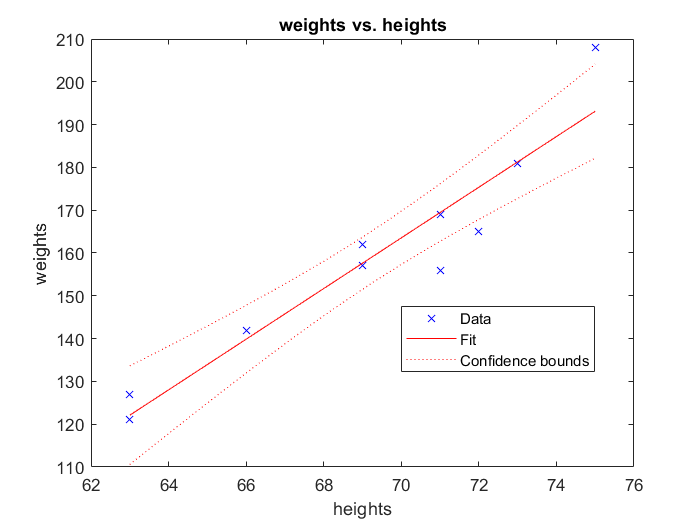

plot(model)

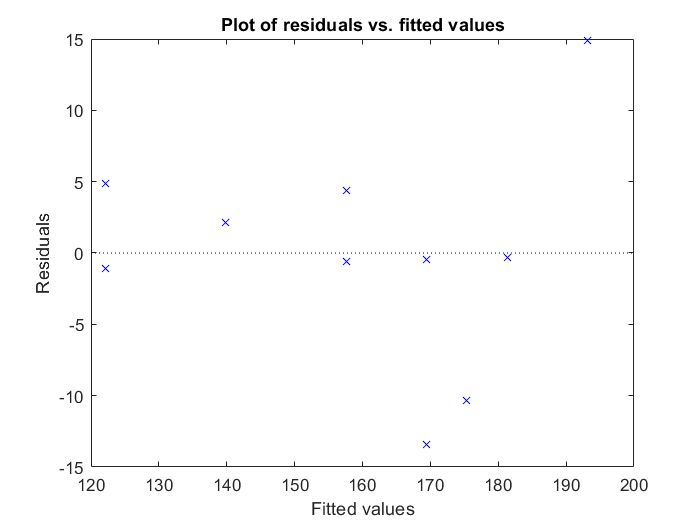

plotResiduals(model,'fitted')

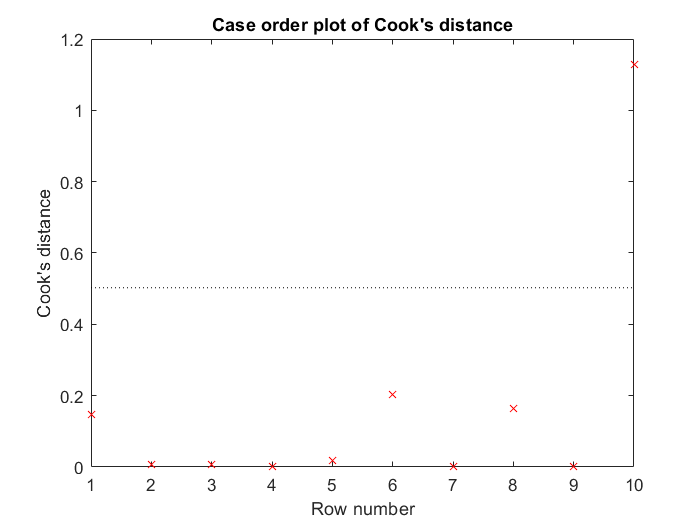

plotDiagnostics(model,'cookd')

**The pair (75, 208) is an outlier and negatively affects the model.**

**Remove it and fit again.**

table1(10,:) = [];
myfit2 = fitlm(table1)

myfit2 = Linear regression model:
    weights ~ 1 + heights

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -193.86      37.286    -5.1992     0.0012542
    heights         5.0644     0.54316     9.3239    3.3875e-05


Number of observations: 9, Error degrees of freedom: 7
Root Mean Squared Error: 5.75
R-squared: 0.925,  Adjusted R-Squared 0.915
F-statistic vs. constant model: 86.9, p-value = 3.39e-05

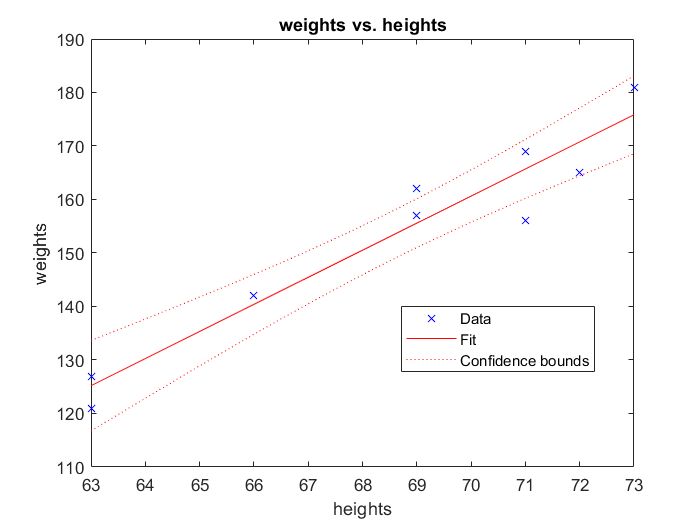

plot(myfit2);

% Predict the values using the model
predict(myfit2,75)

ans = 185.9703

predict(myfit2,0)

ans = -193.8564

predict(myfit2,65)

ans = 135.3267

predict(myfit2,80)

ans = 211.2921